%take generic Lorenz system as an example to show main framework of FRMM
[t,y]=ode45('Genericlorenz',[0 40],[2 2 2]);% Generate discrete Lorenz data
sigmaK=8,alpha=1, d=2;% d is the embedded dimension

sigmaK = 8

alpha = 1

[YxY] = diffusionKernel (y,sigmaK,alpha,d)%feature embedding based on diffusion map

YxY =    -0.0128    2.6526
   -0.0153    2.6549
   -0.0177    2.6571
   -0.0202    2.6593
   -0.0227    2.6614
   -0.0356    2.6711
   -0.0494    2.6790
   -0.0644    2.6846
   -0.0810    2.6874
   -0.1034    2.6855


i=1,tau=5;E=2;%for exmaple

i = 1

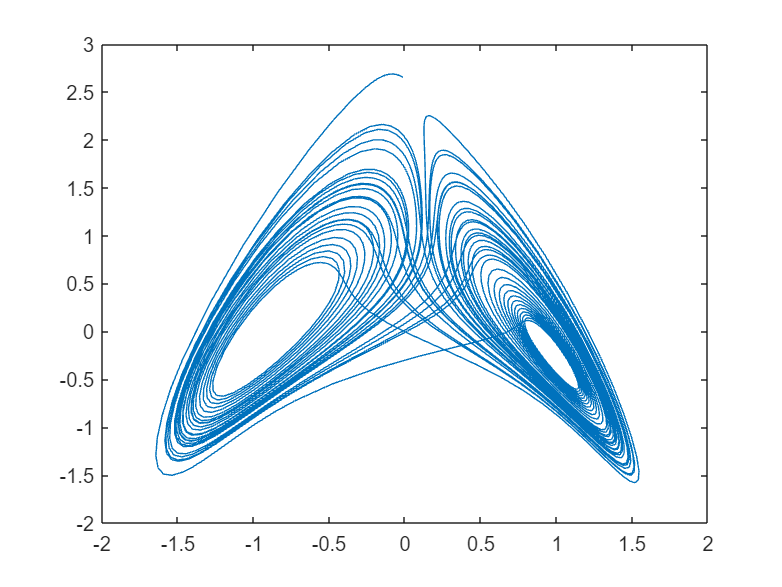

plot(YxY(:,1),YxY(:,2));% 2-dimensional feature embedding of Lorenz attractor 

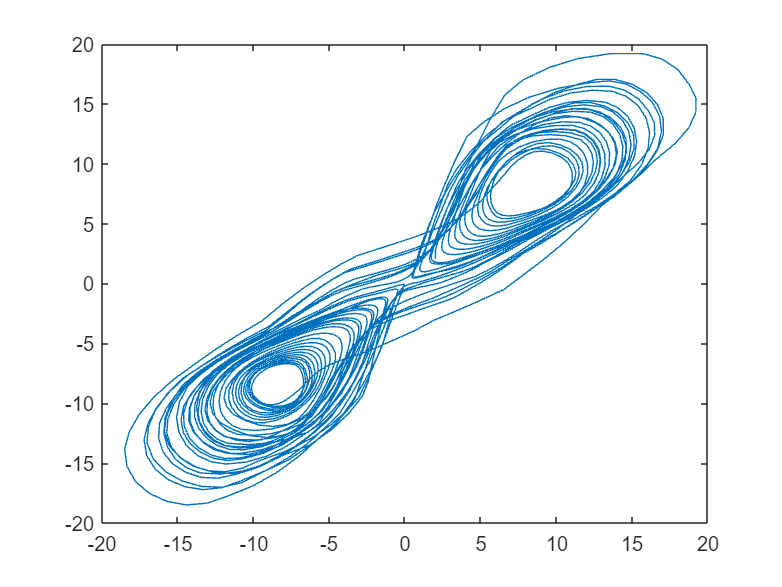

ss=PhaSpaRecon(y(:,i),tau,E);% delay embedding.i represent the i-th variable
Y=ss';
plot(Y(:,1),Y(:,2))% Reconstructed Lorenz attractor 

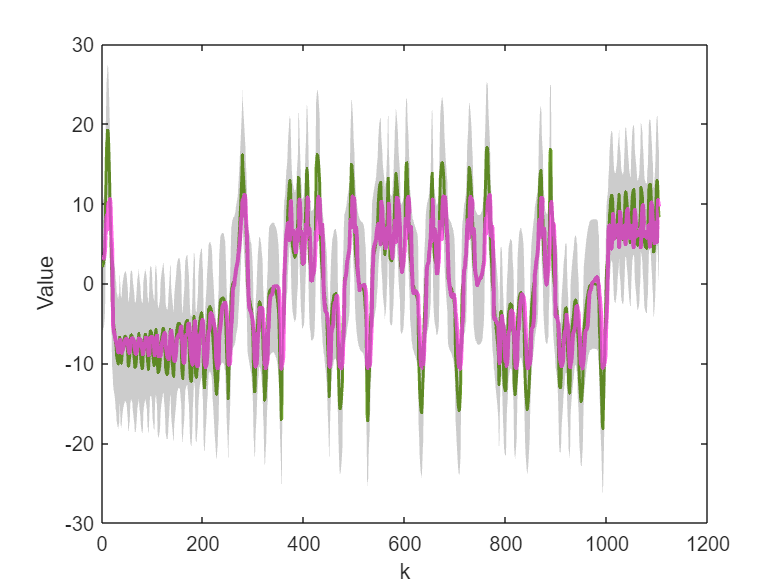

Xy=YxY ;%predictor
Y=Y ;%target
rng(10)
N=length(Y);
cvp = cvpartition(N,'Holdout',0.5);%propotion of traning sample
idxTrn = training(cvp); % Training set indices
idxTest = test(cvp);    % Test set indices
Xtrain = Xy(idxTrn,:);
Ytrain = Y(idxTrn,2);
[Ztrain,tr_mu,tr_sigma] = zscore(Xtrain); 
tr_sigma(tr_sigma==0) = 1;
Mdl = fitrkernel(Ztrain,Ytrain);
Xtest = Xy(idxTest,:);
Ztest = (Xtest-tr_mu)./tr_sigma;
Ytest = Y(idxTest,2);
YFit = predict(Mdl,Ztest);
L = loss(Mdl,Ztest,Ytest);
LL=(L^0.5)./std(Ytest);%RMSE
YY=[YFit Ytest];
CO=corr(YY);% Rou
plot(Ytest,'-','color',[0.46,0.67,0.18],'linewidth',1.5);hold on; plot(YFit,'-','color',[1,0.4,0.9],'linewidth',2);

%legend('Original','Predicted');
xlabel 'k'
ylabel 'Value'
STD=std(Ytest);
xy=1:1:length(Ytest(:,1)-1);
xy=xy';
y1=Ytest-std(Ytest);
y2=Ytest+std(Ytest);
Yy=[y1 y2];
patch([xy;flipud(xy)],[Yy(:,1);flipud(Yy(:,2))],'k','FaceA',.2,'EdgeA',0) 